# Getting started

Main publication: Santosa, H., Zhai, X., Fishburn, F., & Huppert, T. (2018). 

  The NIRS brain AnalyzIR toolbox. *Algorithms*, *11*(5), 73.

[https://www.mdpi.com/1999-4893/11/5/73](https://www.mdpi.com/1999-4893/11/5/73)

Git Desktop

  [https://desktop.github.com/](https://desktop.github.com/) 

Source Tree

  [https://www.sourcetreeapp.com/](https://www.sourcetreeapp.com/)

## Step-by-step

This guide will show you how to get started using the Brain AnalyzIR toolbox

Step 1: Download and install the github Desktop

Link: [https://desktop.github.com](https://desktop.github.com)

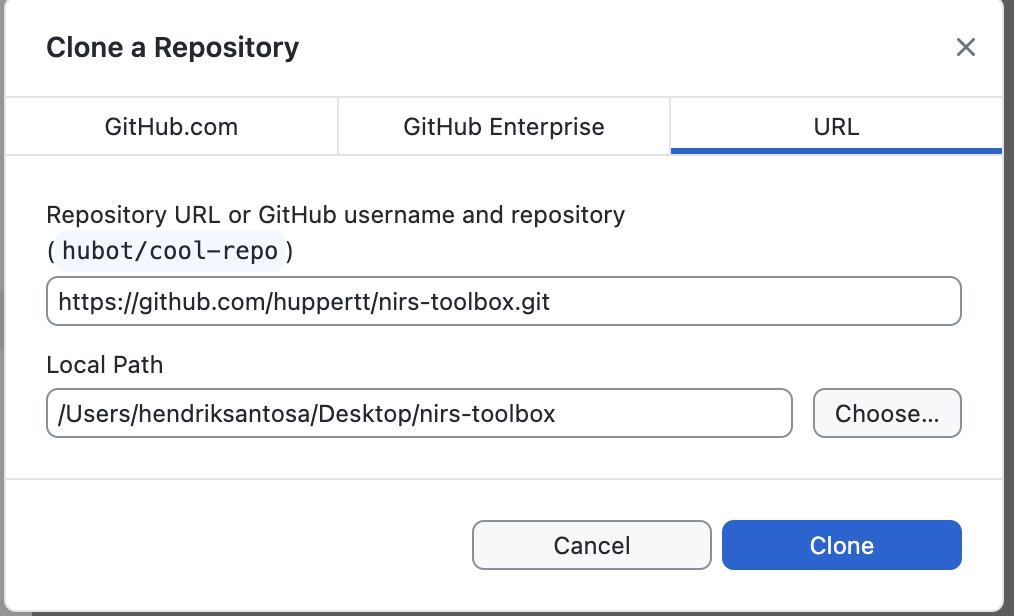

Step 2. Clone the Repository

Clone the repository using the following link: [https://github.com/huppertt/nirs-toolbox.git](https://github.com/huppertt/nirs-toolbox.git)

Step 3. Path

    1. Type pathtool in Matlab command window

    2. Add Folder: 'Desktop/nirs-toolbox'

    3. Add with Subfolders: 'Desktop/nirs-toolbox/demos'

    4. Add with Subfolders: 'Desktop/nirs-toolbox/external'

    5. With all the external folders still selected, click "Move to Bottom"

Step 4. Testing

This step ensures that you have correctly installed the AnalyzIR toolbox. In the MATLAB Command Window, type 'nirs.' and press the Tab Key.

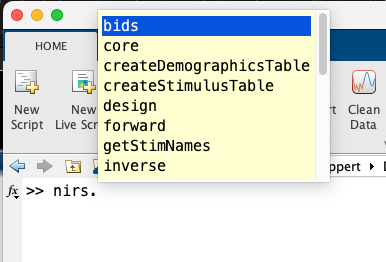

**RUN THIS**

You can try running this simple script in MATLAB to see if the toolbox is working properly on your computer: 

% This is only run the first level stats from sim data, then plot the hbo
clear all; clc;
raw = nirs.testing.simData([], @(t)nirs.testing.blockedStimDesign(t,10,20));
job = nirs.modules.default_modules.single_subject;
Stats = job.run(raw);

Import data module skipped: Data provided
Hb created in workspace
................................Finished    1 of    1.
SubjStats created in workspace


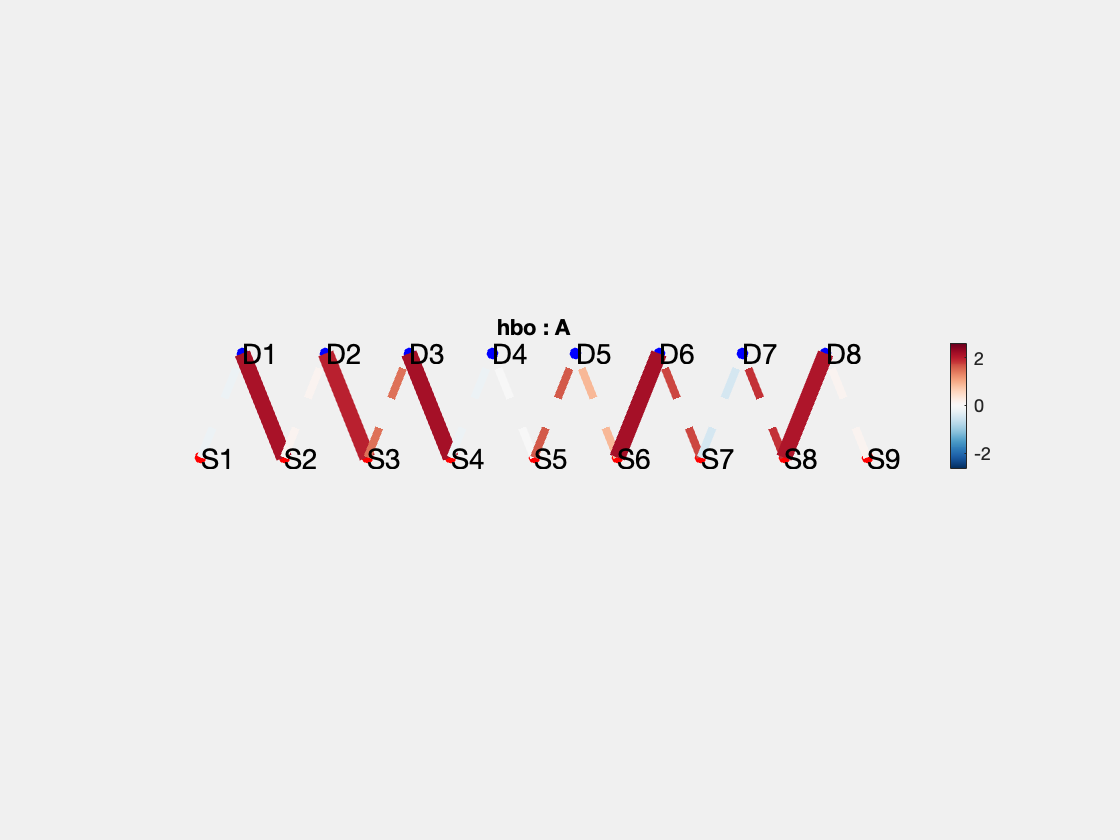

Stats.draw('tstat',[],'p<0.05',[],[],'hbo');

**If you encounter an error related to "Signal Processing Toolbox"**

    1. Unzip 'Desktop/nirs-toolbox/external/matlab/toolbox.zip'

    2. Type 'Pathtool' in the Command Window

    3. Add with Subfolders: 'Desktop/nirs-toolbox/external/matlab/toolbox'